# Classification Algorithms

## เริ่มด้วย Iris

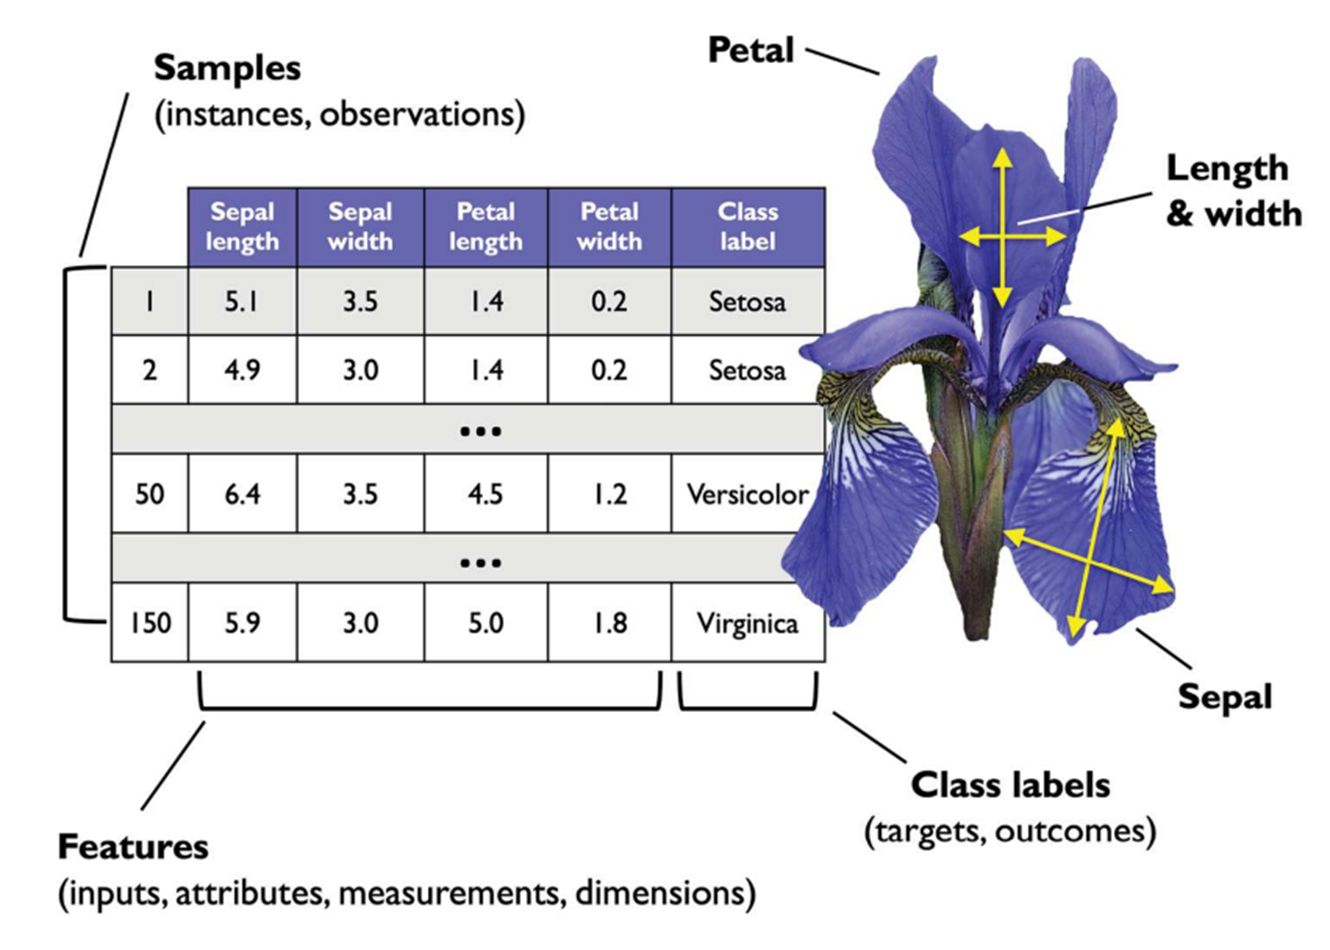

load fisheriris;

meas

meas =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


species

species = 150×1 cell array
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}


## การเตรียมข้อมูลฝึกฝน

% Shuffle data
numSamples = length(species);
idx = randperm(numSamples);
X = meas(idx, :);
y = species(idx);

% Split into training set and test set
hpartition = cvpartition(y, 'Holdout', 0.2); % stratified partitioning

idxTrain = training(hpartition);
idxTest = test(hpartition);

XTrain = X(idxTrain, :);
yTrain = y(idxTrain);

XTest = X(idxTest, :);
yTest = y(idxTest);

## ฝึกฝนโมเดล

- Decision tree

- Support vector machine

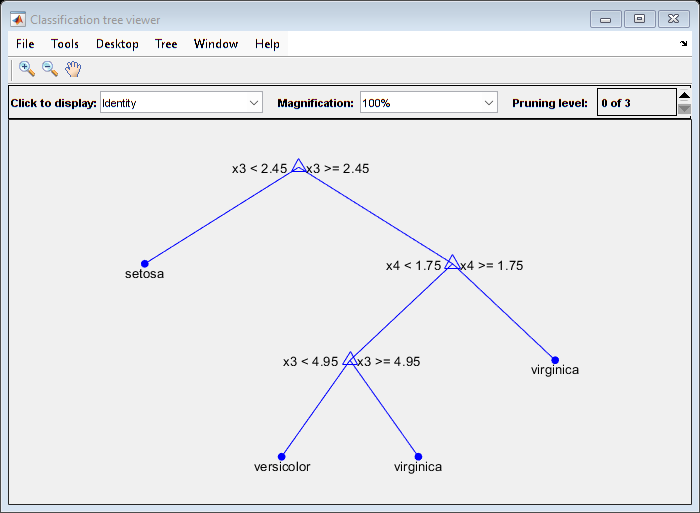

treeModel = fitctree(XTrain, yTrain);

view(treeModel, 'Mode', 'graph');


labels = predict(treeModel, XTest);
numCorrect = sum(cellfun(@isequal, labels, yTest));

[m, order] = confusionmat(yTest, labels);
precision = diag(m) ./ sum(m, 2);
recall = diag(m) ./ sum(m, 1)';

% model = fitcsvm(XTrain, yTrain); % 2-class only
model = fitcecoc(XTrain, yTrain);
% model = fitcnb(XTrain, yTrain);

labels = predict(model, XTest);
numCorrect = sum(cellfun(@isequal, labels, yTest));

[m, order] = confusionmat(yTest, labels);
precision = diag(m) ./ sum(m, 2);
recall = diag(m) ./ sum(m, 1)';